# Two-Train Example - Q-leanring

**Author**: Michel Barbeau

**Version**: September 13, 2021

## Agent and Its World

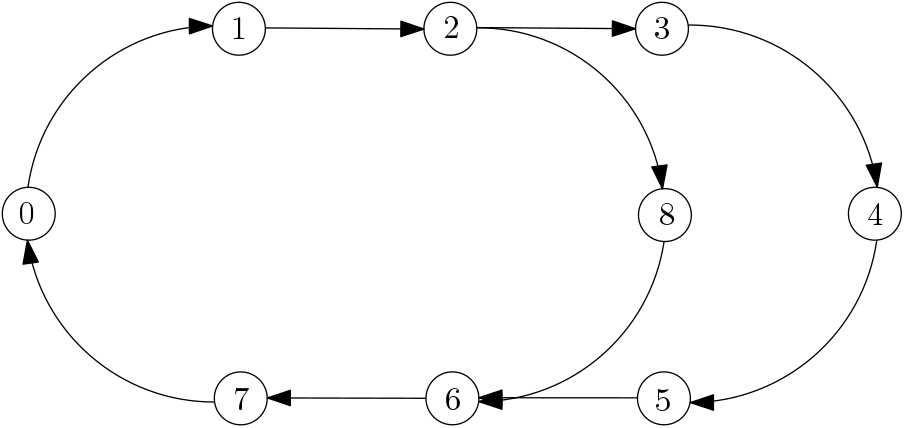

We consider a discrete two-train configuration. Tracks are broken into sections. Let us assume a scenario where Train 1 is the agent and Train 2 is part of its world. There is an outer loop visiting points 3, 4 and 5, together with a bypass from point 2, visiting point 8 to point 6. Traversal time is uniform across sections. The normal trajectory of Train 1 is the outer loop, while maintaining a distance greater than one empty section with Train 2. For example, if Train 1 is at point zero while Train 2 is at point 7, then the separation distance constraint is violated.

When a train crosses point 0, it has to make a choice: either traverse the outer loop or take the bypass. Both trains can follow any path and make independent choices,  when they are at point 0.

In the terms of reinforcement learning, Train 1 has two actions available: take loop and take bypass. The agent gets $k$ reward points for a relative distance increase of $k$ sections with Train 2. It gets $-k$ reward points, i.e., a penalty,  for a relative distance decrease of $k$ sections with Train 2. For example, let us assume that Train 1 is at point 0 and that Train 2 is at point 7. If both trains, progressing a the same speed, take the loop or both decide to take the bypass, then there is no relative distance change. The agent gets no reward. When Train 1 decides to take the bypass and Train 2 decides to take the loop, the agent gets two reward points, at return to point zero (Train 2 is at point five). When Train 1 decides to take the loop and Train 2 decides to take the bypass, the agent gets four reward points, at return to point zero (Train 2 is at point one).

## MDP Model

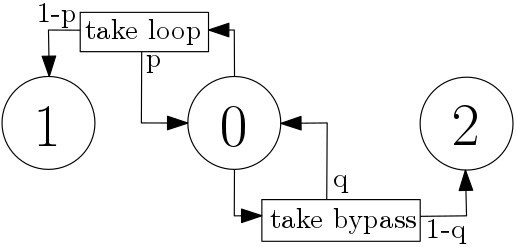

In the MDP model, the state set is $$S=\{ 0, 1,2 \}$$. The action set is $$A=\{ a_0=\mbox{take loop},  a_1=\mbox{take bypass} \}$$.

The transition probability function is defined as $$P_{a_0}(0,0)=p$,   $P_{a_0}(0,1)=1-p$, $P_{a_1}(0,0)=q$$ and $$P_{a_1}(0,2)=1-q$$. The reward functions is defined as $$R_{a_0}(0,0)=0$, $R_{a_0}(0,1)=4$, $R_{a_1}(0,0)=0$$ and $$R_{a_1}(0,2)=2$$. This is interpreted as follows. In the initial state 0 with a one-section separation distance, the agent selects an action to perform: take loop or take bypass. Train 1 performs the selected action. When selecting take loop, with probability $$p$$ the environment goes back to state 0 (no reward) or with probability $$1-p$$ it moves to state 1, with a five-section separation distance (reward is four). When selecting take bypass, with probability $$q$$ the environment goes back to state 0 (no reward) or with probability $$1-q$$ it moves state 2, with a three-section separation distance (reward is two). States 1 and 2 are terminal. This example is small enough to conclude, without the help of the computer, that the best choice is always to for Train 1 to choose the action, $p$ greater than zero. This statement is valid for the initial state as specified and regardless of the values of the probabilities of $p$ and $q$. The reward is approaching as $p$ gets close tone zero.

## Matlab

See: 

[Train Reinforcement Learning Agent in MDP Environment - MATLAB & Simulink (mathworks.com)](https://www.mathworks.com/help/reinforcement-learning/ug/train-reinforcement-learning-agent-in-mdp-environment.html)

[Q-learning reinforcement learning agent - MATLAB (mathworks.com)](https://www.mathworks.com/help/reinforcement-learning/ref/rlqagent.html)

[Options set for reinforcement learning agent representations (critics and actors) - MATLAB (mathworks.com)](https://www.mathworks.com/help/reinforcement-learning/ref/rlrepresentationoptions.html)

Create an MDP model with three states and two actions.

MDP = createMDP(3,["a0";"a1"]);

Specify the state transition and reward matrices for the MDP. 

% probabilities
%p = 1;
%q = 0;
Qa0=zeros(11,11); % Q-values for action a0, from state 0
Qa1=zeros(11,11); % Q-values for action a1, from state 1
i=1;
for p=0:0.1:1
    j=1;
    for q=0:0.1:1
        % MDP.T(from-state,to-state,action) = probability;
        MDP.T(1,[1 2],1) = [p 1-p];
        MDP.T(1,[1 3],2) = [q 1-q]; % Action a1
        % MDP.R(from-state,to-state,action) = reward;
        MDP.R(1,1,1) = 0; % Action a0 (take loop), Train 2 two same
        MDP.R(1,2,1) = 4; % Trains 2 takes bypass
        MDP.R(1,1,2) = 0; % Action a1 (take bypass), Train 2 two same
        MDP.R(1,3,2) = 2; % Trains 2 takes loop

Specify terminal states.

        MDP.TerminalStates = ["s2";"s3"];

Create the reinforcement learning MDP environment.

        env = rlMDPEnv(MDP);

Specify that the initial state of the agent is always state 1, with a reset function.

        env.ResetFcn = @() 1;

Fix the random generator seed.

        rng(0);

## Create Q-Learning Agent

        % create a Q table using the observation and action specifications
        obsInfo = getObservationInfo(env);
        actInfo = getActionInfo(env);
        qTable = rlTable(obsInfo, actInfo);
        qRepresentation = rlQValueRepresentation(qTable, obsInfo, actInfo);
        qRepresentation.Options.LearnRate = 1;
        % create a Q-learning agent using this table representation, configuring the epsilon-greedy exploration
        agentOpts = rlQAgentOptions;
        agentOpts.DiscountFactor = 1;
        agentOpts.EpsilonGreedyExploration.Epsilon = 0.9;
        agentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01;
        qAgent = rlQAgent(qRepresentation,agentOpts);

## Train Q-Learning Agent

        trainOpts = rlTrainingOptions;
        trainOpts.MaxStepsPerEpisode = 50;
        trainOpts.MaxEpisodes = 200;
        trainOpts.StopTrainingCriteria = "AverageReward";
        trainOpts.StopTrainingValue = 13;
        trainOpts.ScoreAveragingWindowLength = 30;
        trainOpts.Verbose = false;
        trainOpts.Plots = "none"; % no visualization
        trainingStats = train(qAgent,env,trainOpts);

## Validate Q-Learning Results

Simulate the agent in the training environment using the sim function.

%Data = sim(qAgent,env);
%cumulativeReward = sum(Data.Reward)

Values in the Q table of the trained agent.

    QTable = getLearnableParameters(getCritic(qAgent));
    Qvalues=QTable{1};
    Qa0(i,j) = Qvalues(1,1);
    Qa1(i,j) = Qvalues(1,2);
    j = j + 1;
    end
    i = i + 1;
end
% display Q-values
disp(Qa0);
disp(Qa1);
% plot the results
figure;
bar3(Qa0);
title('$Q(0,a_0)$','interpreter','latex')
xlabel('$p$','interpreter','latex');
xticklabels({'0','','','','','0.5','','','','','1'});
ylabel('$q$','interpreter','latex');
yticklabels({'0','','','','','0.5','','','','','1'});
figure;
bar3(Qa1);
title('$Q(0,a_1)$','interpreter','latex')
xlabel('$p$','interpreter','latex');
xticklabels({'0','','','','','0.5','','','','','1'});
ylabel('$q$','interpreter','latex');
%yticklabels({'0','0.1','0.2','0.3','0.4','0.5','0.6','0.7','0.8','0.9','1'});
yticklabels({'0','','','','','0.5','','','','','1'});

## Fixed Probability Example

Create an MDP model with three states and two actions.

MDP = createMDP(3,["a0";"a1"]);

Specify the state transition and reward matrices for the MDP. 

% DL enabled
% attack scenario probabilities (adversary learned what the agent probably does) 
p = 0.9; % high prob. of adversary doing same as agent
q = 0.9;
% MDP.T(from-state,to-state,action) = probability;
MDP.T(1,[1 2],1) = [p 1-p];
MDP.T(1,[1 3],2) = [q 1-q]; % Action a1
% MDP.R(from-state,to-state,action) = reward;
MDP.R(1,1,1) = 0; % Action a0 (take loop), Train 2 two same
MDP.R(1,2,1) = 4; % Trains 2 takes bypass
MDP.R(1,1,2) = 0; % Action a1 (take bypass), Train 2 two same
MDP.R(1,3,2) = 2; % Trains 2 takes loop

Specify terminal states.

MDP.TerminalStates = ["s2";"s3"];

Create the reinforcement learning MDP environment.

env = rlMDPEnv(MDP);

Specify that the initial state of the agent is always state 1, with a reset function.

env.ResetFcn = @() 1;

Fix the random generator seed.

rng(0);

## Create Q-Learning Agent

% create a Q table using the observation and action specifications
obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);
qTable = rlTable(obsInfo, actInfo);
qRepresentation = rlQValueRepresentation(qTable, obsInfo, actInfo);
qRepresentation.Options.LearnRate = 1;
% create a Q-learning agent using this table representation, configuring the epsilon-greedy exploration
agentOpts = rlQAgentOptions;
agentOpts.DiscountFactor = 1;
agentOpts.EpsilonGreedyExploration.Epsilon = 0.9;
agentOpts.EpsilonGreedyExploration.EpsilonDecay = 0.01;
qAgent = rlQAgent(qRepresentation,agentOpts);

## Train Q-Learning Agent

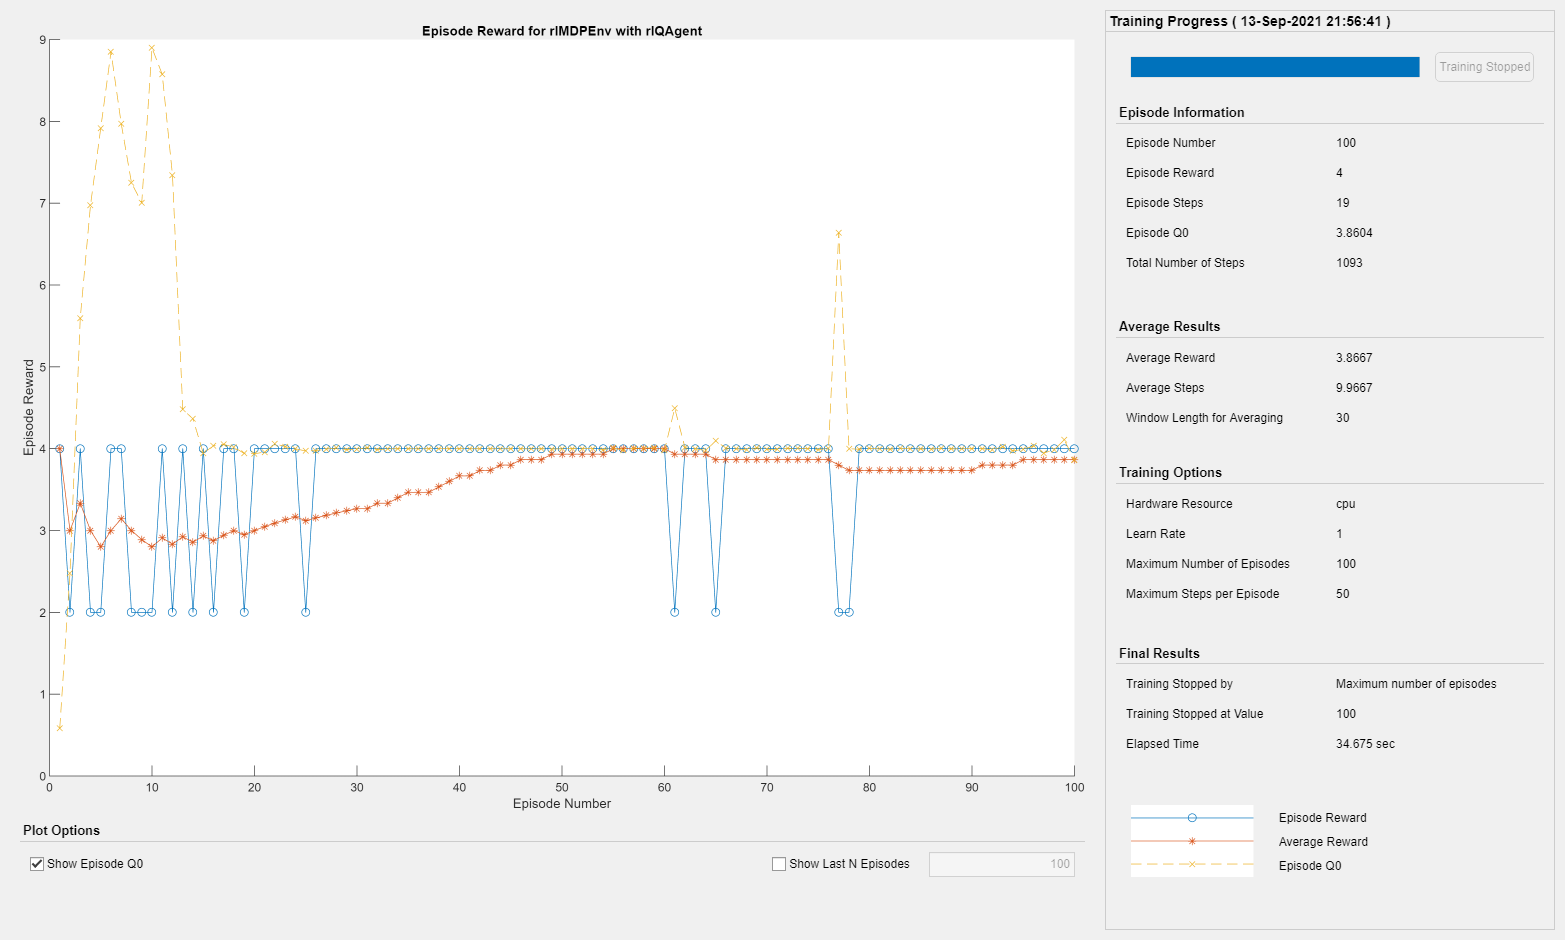

trainOpts = rlTrainingOptions;
trainOpts.MaxStepsPerEpisode = 50;
trainOpts.MaxEpisodes = 100;
trainOpts.StopTrainingCriteria = "AverageReward";
trainOpts.StopTrainingValue = 13;
trainOpts.ScoreAveragingWindowLength = 30;
trainOpts.Verbose = false;
%trainOpts.Plots = "none"; % no visualization
trainingStats = train(qAgent,env,trainOpts);

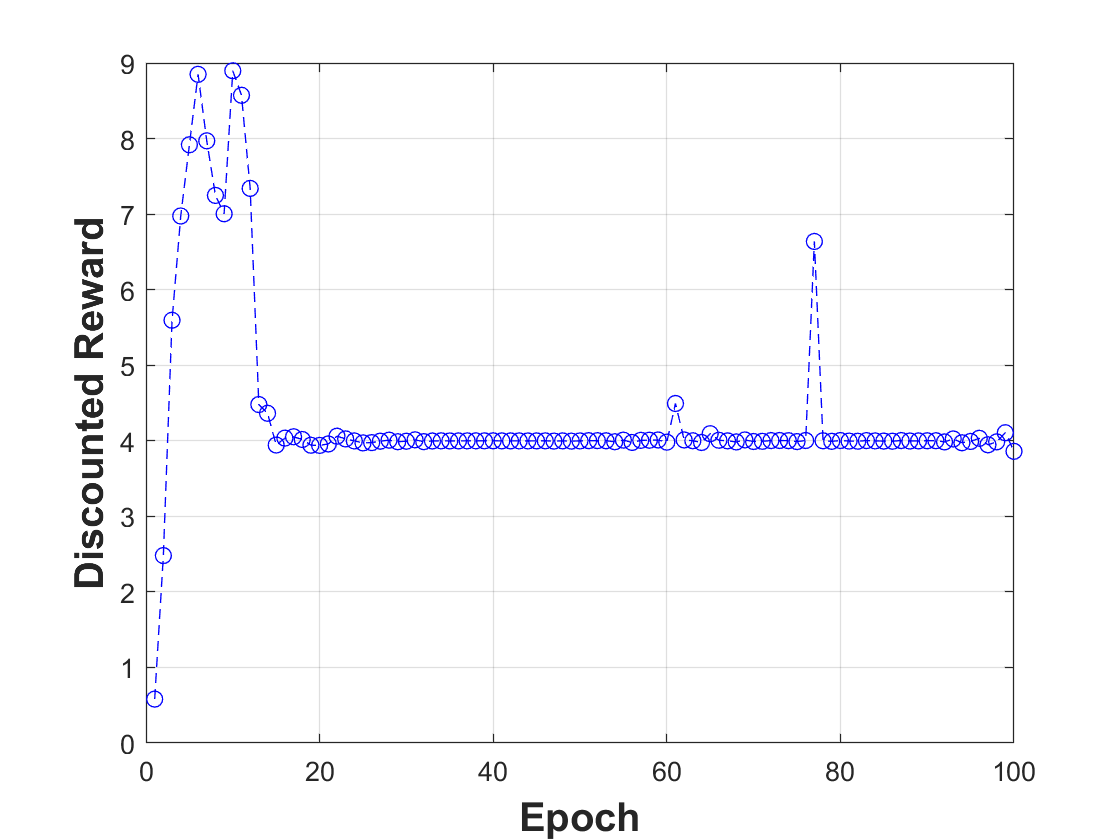

%% With defence learning
figure;
% Discounted reward
DiscountedReward = trainingStats.EpisodeQ0';
plot(1:length(DiscountedReward),DiscountedReward,'b--o');
xl = xlabel('Epoch');
set(xl, 'FontSize', 15,'fontweight','bold');
yl = ylabel('Discounted Reward');
set(yl, 'FontSize', 15,'fontweight','bold');
yticks([0 1 2 3 4 5 6 7 8 9]);
ylim([0 9])
grid on;